# DSZOB, cvičenie 7.

## **Zadanie:**

## **Úloha 1 - Formantová analýza**

Načítajte si nahrávku z dokumentového servera (vowels.m4a).

Vykonajte analýzu jednotlivých samohlások pomocou spektrogramu v danej nahrávke. Identifikujte hodnoty jednotlivých formantov. Na základe tabuľky sa pokúste identifikovať o aké anglické samohlásky ide. Overte si výpočet vypočutím nahrávky.

Ako pomôcku môžete použiť nasledujúcu tabuľku:

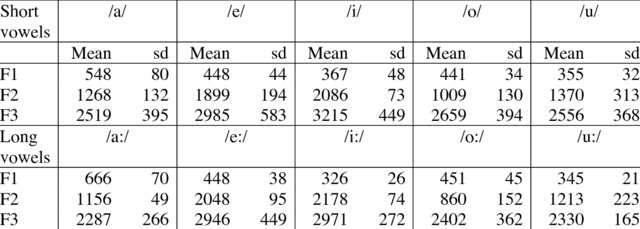

**Solution:**

### 1.1 Načítali sme si nahrávku z dokumentového servera (vowels.m4a).

% Riešenie / Solution
speech = importdata("vowels.m4a");
% speech = importdata("Hlas1.m4a");
fs = speech.fs;
rawSignal = speech.data();
rawSignal = rawSignal';
rawSingalLength = length(rawSignal);
maxTime = rawSingalLength / fs;
timeline = 0:maxTime/(rawSingalLength-1):maxTime;



####     1.1.1 Ktorej sme vizualizovali spektrálny graf, v úseku kde sa nachádzaju prvé tri úseky hlások.

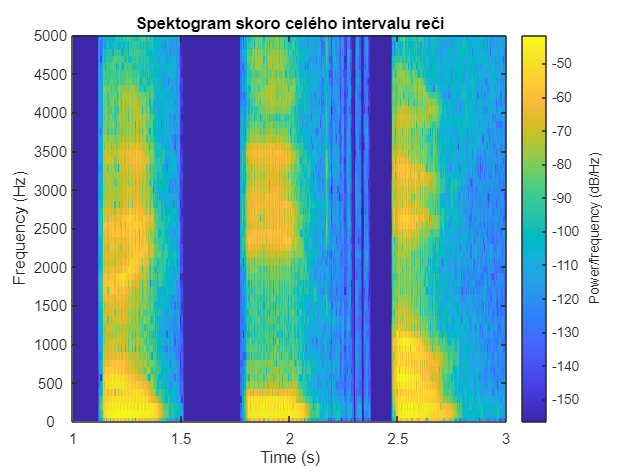

figure
     spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
     title('Spektogram skoro celého intervalu reči')
     set(gca,'YTickLabel', (0:5000/10:5000))
     ylabel('Frequency (Hz)')
     ylim([0 5])
     xlim([1 3])

#### 1.1.2 Tieto úseky hlásom sme ešte raz vizualizovali, ale osobitne

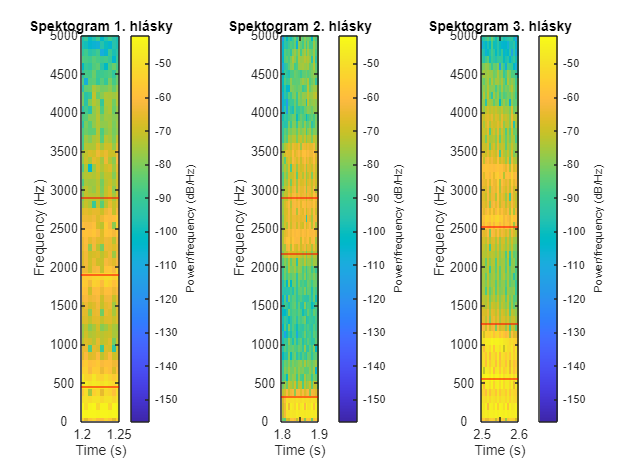

figure
    tiledlayout(1,3)
            nexttile
     spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
     title('Spektogram 1. hlásky')
     set(gca,'YTickLabel', (0:5000/10:5000))
     ylabel('Frequency (Hz)')
     ylim([0 5])
     xlim([1.2 1.25])
     hold on
     yline([0.448 1.899 2.895],Color="red")
     hold off
     
            nexttile
     spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
     title('Spektogram 2. hlásky')
     set(gca,'YTickLabel', (0:5000/10:5000))
     ylabel('Frequency (Hz)')
     ylim([0 5])
     xlim([1.8 1.9])
     hold on
     yline([0.326 2.178 2.9],Color="red")
     hold off
            nexttile
     spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
     title('Spektogram 3. hlásky')
     set(gca,'YTickLabel', (0:5000/10:5000))
     ylabel('Frequency (Hz)')
     ylim([0 5])
     xlim([2.5 2.6])
     hold on
     yline([0.548 1.268 2.519],Color="red")
     hold off

rec1 = audioplayer(rawSignal, fs);

playblocking(rec1,  [round(1*fs),round(1.5*fs)])   %ej
playblocking(rec1,  [round(1.8*fs),round(2.3*fs)]) %i
playblocking(rec1,  [round(2.4*fs),round(2.8*fs)]) %ou


Nájdené **Formanty u jednotlivých hláskach:**

- **cca. 500Hz,  1800-2000Hz, 2480-2500Hz**

- **cca. 300-400HZ, 2200-2500Hz, 2700-2900hz,**

- **cca. 500Hz, 1000Hz, 2600Hz **

**Podla týchto hôdnot odhadujem pismena pre jednotlivé hlásky nasledovne:**

- Podla podmienok toho že tam nie us blizke hodnoty okolo 1000, ale tesno pri 3000, tak vypadáva **a o u,** a najpravdepodobnejšie hláska je **short** ** e, **vzhladom na F2 blizke 2000 ale stále pod ním**, **s** F1=448, F2=1899, F3=2985**, až na ten posledný parameter

- Opäť vyradovacou metodou to podla podmienok nebude** a o** ani **u, je to pravdepodobne long i:, s hodnotami F1=326, F2=2178, F3=2900**

- Podla prvých troch prbližných hodnot, vypadáva **e i, **pričom najpravdepobnejšia hláska  bola identifikovaná táto hlaska ako **short** **a**, **s F1=548, F2=1268, F3=2519, **alebo** o **

**Podla nahrávok určujem tieto hlásky nasledovne:**

- **ej **

- **i**

- **ou**

        Je potrebné poznamenať že síce hlásky by mali byť anglické, zápis /a/ prislúcha k vyslovnosti, teda blood sa vyslovuje bl/a/d, a /i:/ keep, k/i:/p. Vzhladom na to boli porovnávané  samohlásky ako znejú v slovenčine a nie ich anglická varianta.

**Vyhodnotenie:**

- Identifikované hlásky boli iba približne polovične zhodné s realne vypočutými hláskami, to bolo jednak tým že v jednom úseku hlásky boli konkretné 2 hlasky, tj. pri 1. a 3. úseku hlásky a tým že pri analýze 3. úseku hlásky, boli určené formanty podobné v 2 hláskach.

## Zadanie 2 - Fundamentálna frekvencia

Pre jednu z hlások z nahrávky vykonajte odhad fundamentálnej frekvencie pomocou complexného cepstra.

- Vezmite okienko 2048 hodnôt zo stredu zvolenej samohlásky

- Pre toto vybrané okno vypočítajte complexné cepstrum (cceps)

- Vizualizujte peak vo výsledku v rozsahu približne 0.002 - 0.01s

- Vypočítte príslušnú frekvenciu nájdeného peaku (f = 1/T)

% Riešenie / Solution

### **2:1 Vzali sme si okienko s 2048 hodnôtami zo stredu zvolenej samohlásky --> **

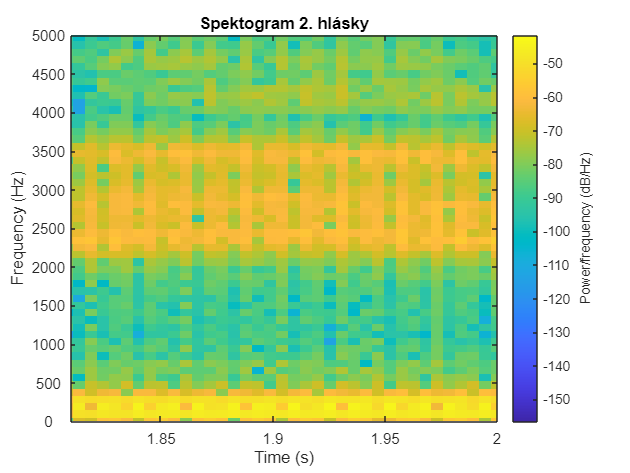

% Výber úseku 2. hlásky
figure
spectrogram(rawSignal, hamming(512), 256, 512, fs, "yaxis")
     title('Spektogram 2. hlásky')
     set(gca,'YTickLabel', (0:5000/10:5000))
     ylabel('Frequency (Hz)')
     ylim([0 5])
     xlim([1.81 2])

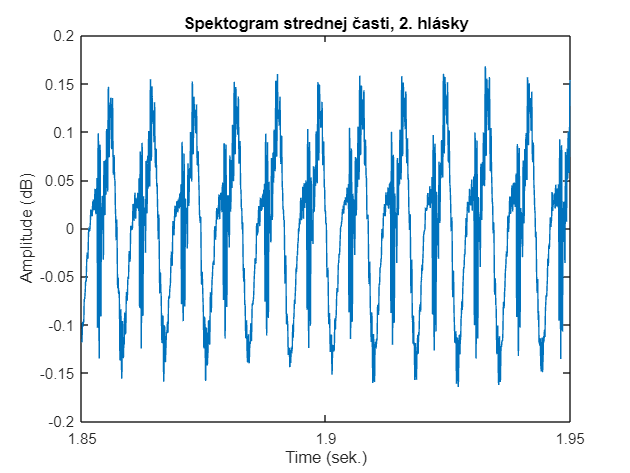

    % priblíženie úseku 2. hlásky
figure
     choosenIndx = 1.85*fs+1:1.95*fs;
     choosenInterval = rawSignal(choosenIndx);
     choosenTimeline = timeline(choosenIndx);
     plot(choosenTimeline,choosenInterval)
     title('Spektogram strednej časti, 2. hlásky')
     xlabel("Time (sek.)")
     ylabel("Amplitude (dB)")

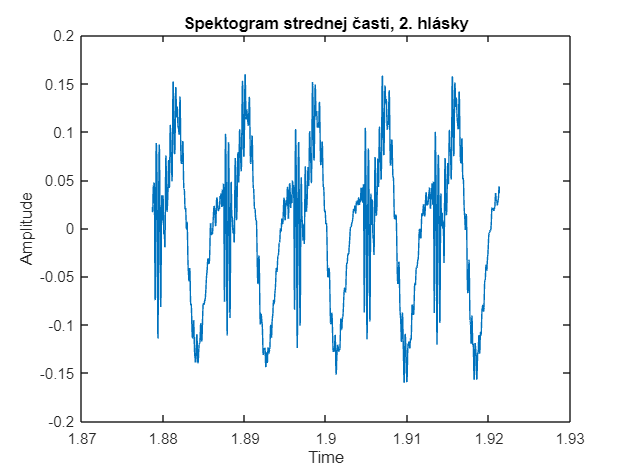

 % výber okna dĺžky 2048 zo strednej časty, vybraného úseku 2. hlásky
halfOfChoosenSignal =  round(length(choosenInterval) / 2);
choosenIndx = halfOfChoosenSignal - 1023:halfOfChoosenSignal + 1024;
choosenTimeline = choosenTimeline(choosenIndx);
figure
     choosenInterval = choosenInterval(:,choosenIndx);
     plot(choosenTimeline,choosenInterval)
     title('Spektogram strednej časti, 2. hlásky dĺžky 2048 time samples')
     xlabel("Time (sek.)")
     ylabel("Amplitude")

### 2.2 Pre toto vybrané okno sme vypočítali complexné cepstrum (pomocou funkcie cceps, do ktorej sme vložili ako jediný parameter, vybrané okno 2048 2. hlasky)

% Výpočet cepstrum za účelom ziskania F0, to je získané po nájdení
% lokalneho maxima pre interval 0.002s až 0.01s výsledného cepstra
cepstrum = cceps(choosenInterval);
approximateInterval = 0.002*fs:0.01*fs;

### 2.3 Vizualizovali sme graf v rozsahu približne 0.002 - 0.01s vysledného cepstrum vectora, kde sme identifikovali peak

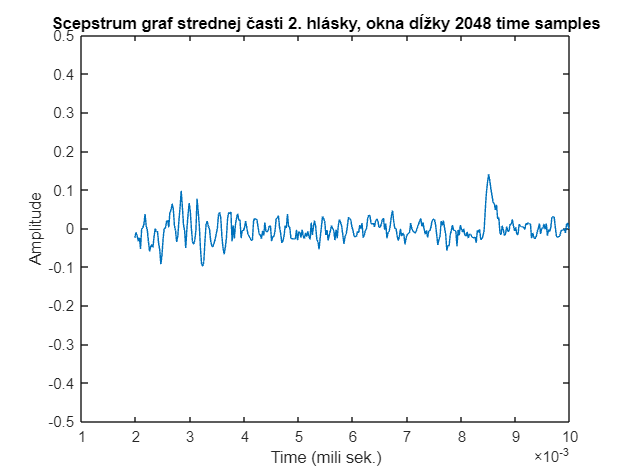

figure
    plot(choosenTimeline(approximateInterval) - choosenTimeline(1),cepstrum(approximateInterval))
    ylim([-0.5 0.5])
    title('Scepstrum graf strednej časti 2. hlásky, okna dĺžky 2048 time samples')
    xlabel("Time (mili sek.)")
    ylabel("Amplitude")

### 2.4 Vypočítali sme príslušnú frekvenciu nájdeného peaku pomocou vzorca (f = 1/T)

% Nájdeme si dané maximum a jeho index
    [M, mIndx] = max(cepstrum(approximateInterval))

M = 0.1397

mIndx = 314

    tempInt = choosenTimeline(approximateInterval);
    T = (tempInt(mIndx)-tempInt(1))

T = 0.0065

    % a použijeme ich pre výpočet freqvencie pre najdený index, pomocou
    % vzorca f = 1/T
    % Kedy periodu sme určily vrámci 2. hlásky, preto sme odčítali čas kedy
    % sa začala
    freq = 1/T;
    % Takto sme získaly frekvenčnú hodnotu F0 = 153Hz
    display("F0 = " + freq + "Hz")

    "F0 = 153.3537Hz"

